# Example 10: Plotting symbolic functions

Here is the code to solve the ODE from the hormone level example:

syms y(t) kappa omega A B y0
sol=dsolve(diff(y)+kappa*y==A+B*cos(omega*t),y(0)==y0)

$$sol = \begin{array}{l} {\mathrm{e}}^{-\kappa \,t}\,\left(y_{0}-\frac{A\,\kappa^{2}+B\,\kappa^{2}+A\,\omega^{2}}{\sigma_{1}}\right)+\frac{A\,\kappa^{2}+A\,\omega^{2}+B\,\kappa^{2}\,\cos\left(\omega \,t\right)+B\,\kappa \,\omega \,\sin\left(\omega \,t\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\kappa \,\left(\kappa^{2}+\omega^{2}\right) \end{array}$$

Notice that the solution is now stored as an object called `sol`.

As before we need to tell the solution what all those parameters are before plotting:

sol=subs(sol,[kappa omega A B y0],[0.05 pi/12 1 1 0])

$$sol = \frac{20\,\left(\frac{\cos\left(\frac{\pi \,t}{12}\right)}{400}+\frac{\pi \,\sin\left(\frac{\pi \,t}{12}\right)}{240}+\frac{\pi^{2}}{144}+\frac{1}{400}\right)}{\frac{\pi^{2}}{144}+\frac{1}{400}}-\frac{20\,{\mathrm{e}}^{-\frac{t}{20}}\,\left(\frac{\pi^{2}}{144}+\frac{1}{200}\right)}{\frac{\pi^{2}}{144}+\frac{1}{400}}$$

Then to plot the solution we can use the command `fplot`. This is very similar to plot, but can take functions as input (rather than having to calculate the function at a bunch of point - no need to define a grid of `t` points via `linspace` here).

The command looks like

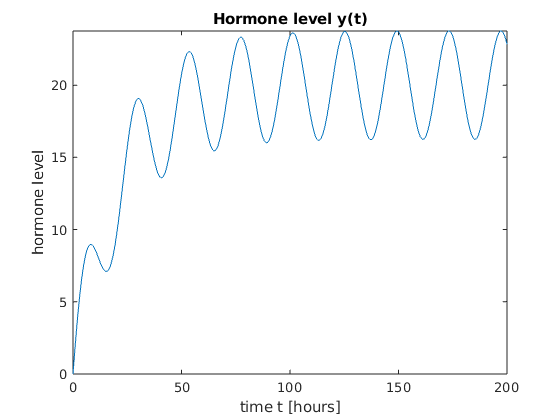

fplot(sol,[0 200])
title('Hormone level y(t)')
xlabel('time t [hours]')
ylabel('hormone level')